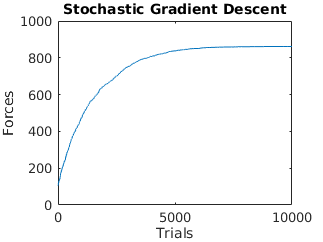

% Creating n Corticalspinal cells
n = 1000;

% Initalize the base CS cells
x_0 = rand(1, n);

% Parameters for zero-mean normal distribution
std_dev = 0.04;
mean = 0;

% CS extensor and flexor connection weights
flexor_c_w= create_cs(0.7, n);
extensor_c_w = create_cs(0.3, n);

% Parameters to translate synaptic drive in MN pool to force
delta = 1;

forces = [];
trials = [];
g = 0.04;  % Learning gain TODO: Aribitrary learning gain for now
f_0 = 0;
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;

    % Synaptic Flexor MN Pools
    s_fi = 0;
    for i = 1:n
        s_fi = s_fi + g_i(x_i(i), flexor_c_w(i));
        % s_fi = s_fi + x_i(i) * c_fi(i);
    end
    % Translate to force
    f_f = delta * s_fi;
    
    % Extensor MN Pool
    s_ei = 0;
    for i = 1:n
        s_ei = s_ei +  g_i(x_i(i), extensor_c_w(i));
        % s_ei = s_ei + x_i(i) * c_ei(i);
    end
    % Translate to force
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    % If it's the first iteration, then there's no past iteration to look
    % at. So continue.
    if trial == 1
        trials = [trial];
        forces = [f_net];

        x_0 = x_i;
        f_0 = f_net;

        continue;
    end

    % Gradient Descent
    x_i_1 = x_i + g * (f_net - f_0) * v_i;
    % Remember the past information
    if f_net > f_0
        x_0 = x_i_1;
        f_0 = f_net;
    end

    trials = [trials, trial];
    forces = [forces, f_0];
end

plot(trials, forces)
title("Stochastic Gradient Descent")
ylim([0, n])
ylabel('Forces')
xlabel('Trials')

saveas(gcf,'images/StochasticGradientDescent.png')